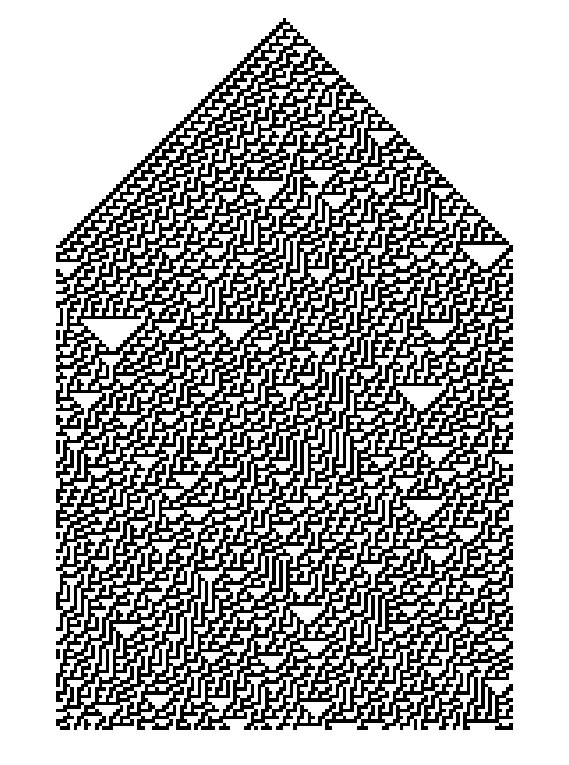

single_black_middle = [zeros(1, 64) 1 zeros(1, 64)];
visualize_rule30(single_black_middle, 200, 1)

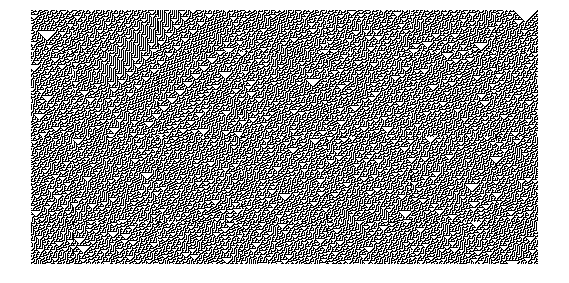

single_black_middle_wider = [zeros(1, 256) 1 zeros(1, 256)];
visualize_rule30(single_black_middle_wider, 256*2, 257)

rng_eca(0);
rng(0);
N = 10^5;
bins = 20;
data_eca = rand_eca(1, N);
data_built_in = rand(1, N);

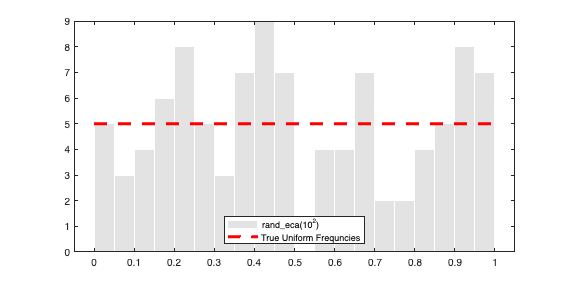

hist_vs_true_uniform(data_eca(1:10^2), bins, "rand\_eca(10^2)");

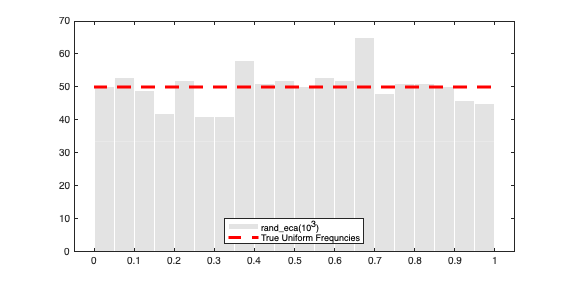

hist_vs_true_uniform(data_eca(1:10^3), bins, "rand\_eca(10^3)");

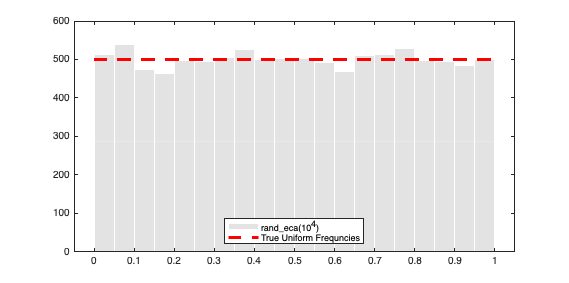

hist_vs_true_uniform(data_eca(1:10^4), bins, "rand\_eca(10^4)");

hist_vs_true_uniform(data_eca(1:10^5), bins, "rand\_eca(10^5)");

fprintf("rand_eca test")

rand_eca test

[observed, theoretical, p_value] = chi_squared_test(data_eca, bins)

observed = 15.2435

theoretical = 30.1435

p_value = 0.7070

fprintf("built-in rand test")

built-in rand test

[observed, theoretical, p_value] = chi_squared_test(data_built_in, bins)

observed = 23.8467

theoretical = 30.1435

p_value = 0.2021

rng_eca(0);
rand_uniform = rand_eca(1, 100);
std_normal = @(x) (1/sqrt(2*pi)) * exp(-(1/2).* (x.^2));
[transformed, areas, target_xs, target_ys] = uniform_to_pdf(rand_uniform, std_normal, -4, 4, 10);

dx = 0.8000

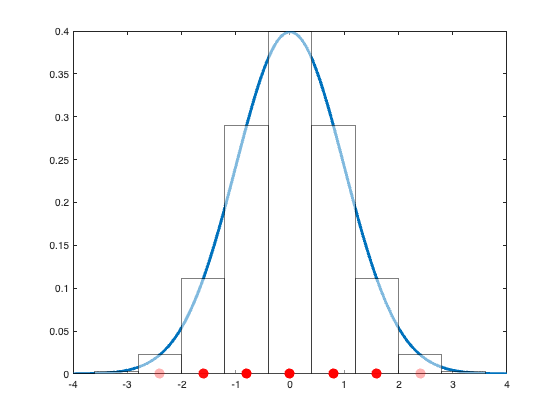


xs = linspace(-4, 4, 1000);
plot(xs, std_normal(xs), "LineWidth",3)
xlim([-4, 4])
hold on
bar(target_xs, target_ys, "BarWidth", 1, "FaceAlpha", 0.5, "EdgeAlpha", 0.5, "FaceColor", [1 1 1])
hold on
scatter( transformed, zeros(1, length(transformed)), "filled", "o", "MarkerFaceAlpha", 0.3, "MarkerFaceColor", [1 0 0], "SizeData", 100)
hold off

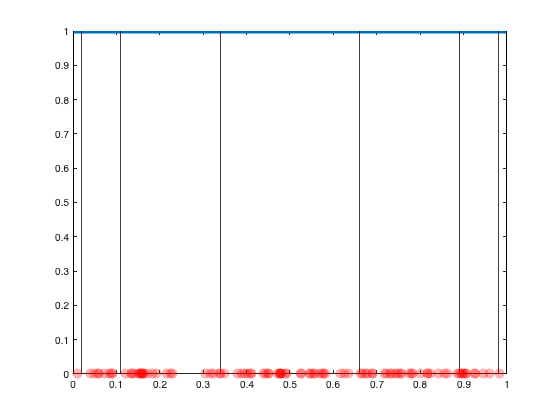


plot([0 1], [1 1], "LineWidth", 5)
hold on
for i=cumsum(areas)
    plot([i i], [0 1], "LineWidth", 1, "Color", [0 0 0])
    hold on
end
scatter(rand_uniform, zeros(1, length(rand_uniform)), "filled", "o", "MarkerFaceAlpha", 0.3, "MarkerFaceColor", [1 0 0], "SizeData", 100)
hold off

rng_eca(0);
rand_uniform = rand_eca(1, 100);
std_normal = @(x) (1/sqrt(2*pi)) * exp(-(1/2).* (x.^2))

std_normal = function_handle with value:
    @(x)(1/sqrt(2*pi))*exp(-(1/2).*(x.^2))


[transformed, areas, target_xs, target_ys] = uniform_to_pdf(rand_uniform, std_normal, -3, 3, 64);

dx = 0.0938

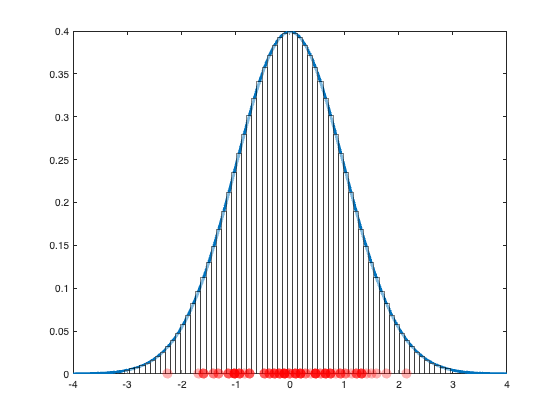


xs = linspace(-4, 4, 1000);
plot(xs, std_normal(xs), "LineWidth",3)
hold on
bar(target_xs, target_ys, "BarWidth", 1, "FaceAlpha", 0.5, "EdgeAlpha", 0.5, "FaceColor", [1 1 1])
hold on
scatter( transformed, zeros(1, length(transformed)), "filled", "o", "MarkerFaceAlpha", 0.3, "MarkerFaceColor", [1 0 0], "SizeData", 100)
hold off

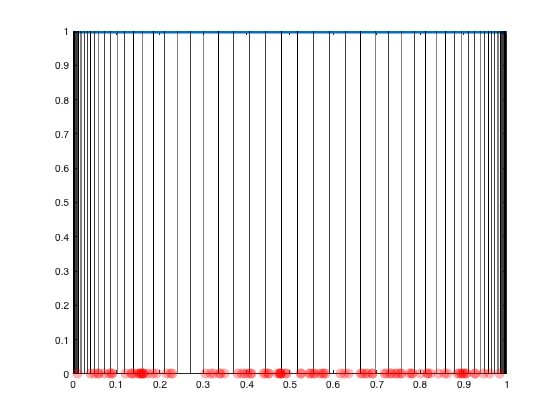


plot([0 1], [1 1], "LineWidth", 5)
hold on
for i=cumsum(areas)
    plot([i i], [0 1], "LineWidth", 1, "Color", [0 0 0])
    hold on
end
scatter(rand_uniform, zeros(1, length(rand_uniform)), "filled", "o", "MarkerFaceAlpha", 0.3, "MarkerFaceColor", [1 0 0], "SizeData", 100)
hold off

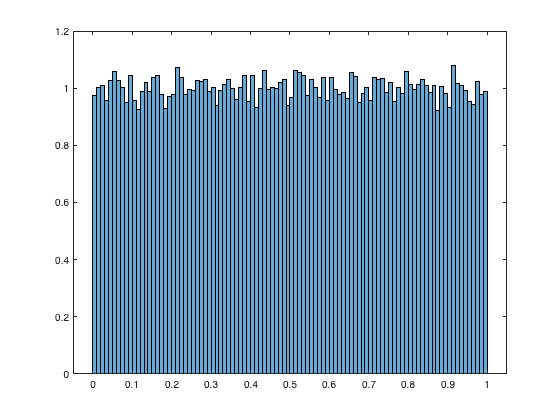

rng_eca(0);
rand_uniform = rand_eca(1, 100000);
std_normal = @(x) (1/sqrt(2*pi)) * exp(-(1/2).* (x.^2));
combined = @(x) (2/3)*std_normal(x-1) + (1/3)*std_normal(x+2);
cauchy = @(x) 1 ./ (pi .* (1+x.^2));
exponential = @(x) exp(-x);
num_rectangles = 10000;
bins = 100;

% uniform (as is)
histogram(rand_uniform, bins, "Normalization", "pdf");

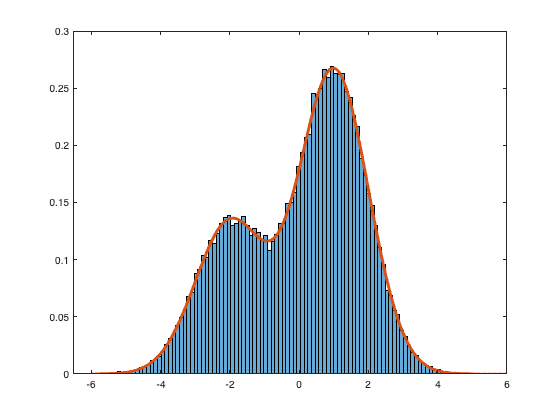



% randomly sampled histogram
a = -6; b = 6; 
histogram(uniform_to_pdf(rand_uniform, combined, a, b, num_rectangles), bins, "Normalization", "pdf")
hold on
xs = linspace(a, b, 1000);
plot(xs, combined(xs), "LineWidth", 3)
hold off

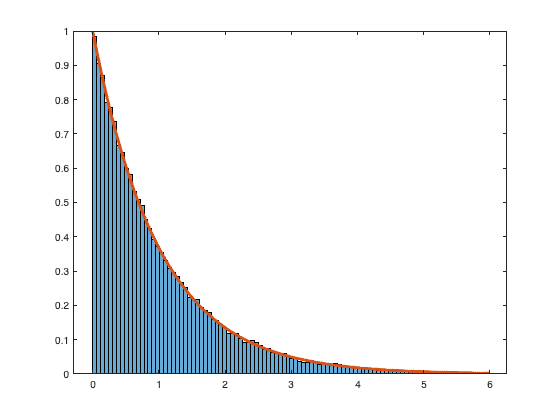


% random exponential sampled  histogram
a = 0; b = 6; 
histogram(uniform_to_pdf(rand_uniform, exponential, a, b, num_rectangles), bins, "Normalization", "pdf")
hold on
xs = linspace(a, b, 1000);
plot(xs, exponential(xs), "LineWidth", 3)
hold off

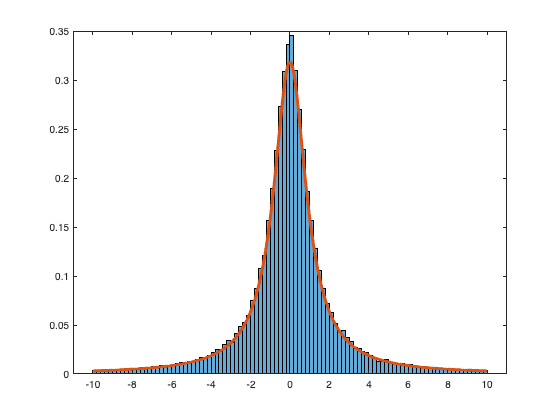


% random exponential sampled  histogram
a = -10; b = 10; 
histogram(uniform_to_pdf(rand_uniform, cauchy, a, b, num_rectangles), bins, "Normalization", "pdf")
hold on
xs = linspace(a, b, 1000);
plot(xs, cauchy(xs), "LineWidth", 3)
hold off